## **Übungszettel 7 - Aufgabe 3**

**Autor: Jan Treiber**

FS = 50000; % Abtastfrequenz in Hz
TD = 0.1; % Aufzeichnungsdauer in s
TS = 1 / FS; % Abtastabstände in s
t = 0:TS:TD-TS; % Abtastzeitraum in s
f1 = 30; % in Hz
f2 = 100; % in Hz
f3 = 200; % in Hz
x = cos(2*pi*f1*t)+sin(2*pi*f2*t)+2*cos(2*pi*f3*t+(pi/2));

% 3)
N = TD/TS; % Anzahl der Abtastwerte
disp("Anzahl der Abtastwerte: " + N);

Anzahl der Abtastwerte: 5000



% 4)
X = fft(x);
counter = length(find(abs(X) > 10^-10)); % Anzahl der Zahlen  größer als 10^-10
disp("Anzahl der Zahlen  größer als 10^-10: " + counter);

Anzahl der Zahlen  größer als 10^-10: 6



% 5)
f0 = 1 / TD;
m1 = f1 / f0;
m2 = f2 / f0;
m3 = f3 / f0;
disp("m1 = " + m1 + "; m2 = " + m2 + "; m3 = " + m3);

m1 = 3; m2 = 10; m3 = 20



% 6)
m_1 = N - m1;
m_2 = N - m2;
m_3 = N - m3;
disp("m-1 = " + m_1 + "; m-2 = " + m_2 + "; m-3 = " + m_3);

m-1 = 4997; m-2 = 4990; m-3 = 4980


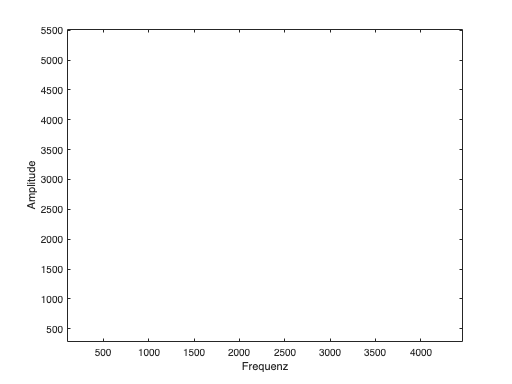


% 7)
n = 0:N-1;
plot(n, abs(X));
xlabel("Frequenz");
ylabel("Amplitude");


% 8)
xm1 = 1/N *  X(m1+1) * exp(j*2*pi*m1*n/N); % Signal nach dem Filter
plot(t, xm1);

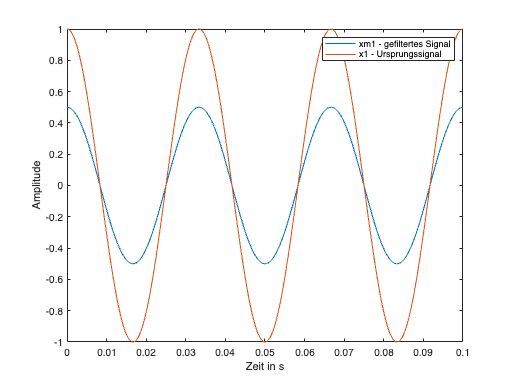

hold on;
x1 = cos(2*pi*f1*t); % ursprünglicher Teil des Signals
plot(t, x1);
hold off;
legend ("xm1 - gefiltertes Signal", "x1 - Ursprungssignal");
xlabel("Zeit in s");
ylabel("Amplitude");


xm2 = 1/N *  X(m2+1) * exp(j*2*pi*m2*n/N); % Signal nach dem Filter
plot(t, xm2);

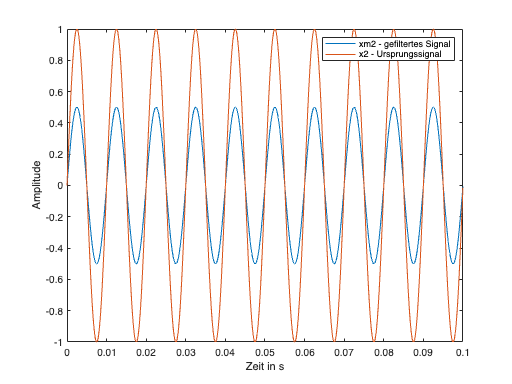

hold on;
x2 = sin(2*pi*f2*t); % ursprünglicher Teil des Signals
plot(t, x2);
hold off;
legend ("xm2 - gefiltertes Signal", "x2 - Ursprungssignal");
xlabel("Zeit in s");
ylabel("Amplitude");


xm3 = 1/N *  X(m3+1) * exp(j*2*pi*m3*n/N); % Signal nach dem Filter
plot(t, xm3);

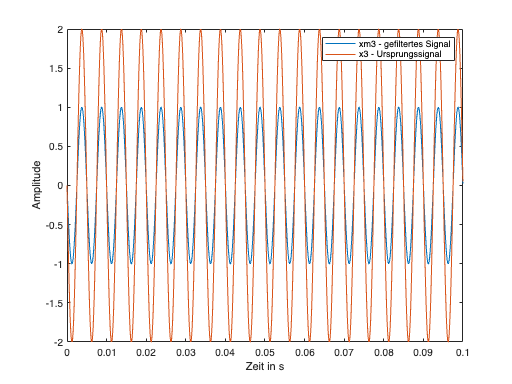

hold on;
x3 = 2*cos(2*pi*f3*t+pi/2); % ursprünglicher Teil des Signals
plot(t, x3);
hold off;
legend ("xm3 - gefiltertes Signal", "x3 - Ursprungssignal");
xlabel("Zeit in s");
ylabel("Amplitude");